# Εργαστήριο Ψηφιακής Επεξεργασίας Σημάτων

## Συμπλήρωμα Αναφοράς 1ης Εργαστηριακής Άσκησης.

#### Λουδάρος Ιωάννης - 1067400

Εδώ περιλαμβάνεται ο κώδικας που χρησιμοποιήθηκε για την εκπόνηση της Άσκησης.

## Άσκηση 1

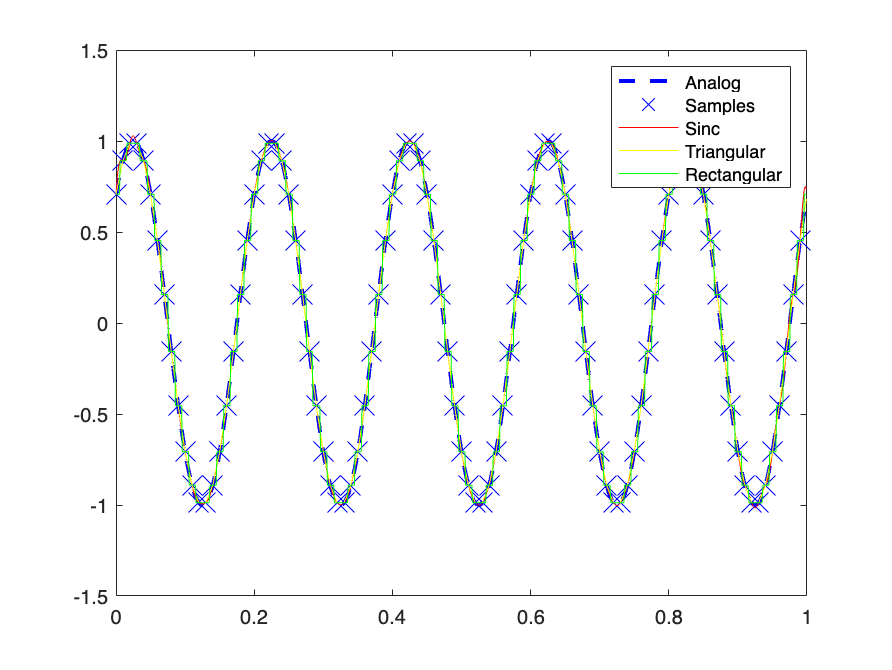

% Ts: sampling rate
% f0: frequency of signal in Hz
% initial_phase: initial phase of signal
%========================================================================%
% clear
% clc
% close all
%========================================================================%
Ts = 0.01;
f0 = 5;
initial_phase =  pi/4;


n  = 0:1/Ts; %discrete samples
%x = sin(2*pi*f0*n*Ts+initial_phase);
x = sin(2*pi*f0*n*Ts+initial_phase);
%plot(n,x)
dt = 0.001;
t = 0:dt:1; %continuous time
x_cont=sin(2*pi*f0*t'+initial_phase);

% Initialize Arrays
sinc_array = zeros(length(t),length(n));
triangular_array = sinc_array;
rec_array = sinc_array;

% indx:(t/Ts-n)
indx = t'*ones(1,length(n))/Ts-ones(length(t),1)*n;

% Sinc
sinc_array = sinc(indx);

% Triangular
triangular_array(abs(indx)>1)=0; %x in [-1, 1], so delete the rest
triangular_array(abs(indx)<1) = 1 - abs(indx(abs(indx)<1));

% Rectangular
rec_array(abs(indx)<1/2) = 1;
rec_array(indx ==1/2) = 1;
rec_array(abs(indx)>1/2) = 0;


% Reconstructed Signals
x_analog1 = sum((ones(length(t),1)*x).*sinc_array,2); % Sinc Reconstruction
x_analog2 = sum((ones(length(t),1)*x).*triangular_array,2); %Triangular Reconstruction
x_analog3 = sum((ones(length(t),1)*x).*rec_array,2); % Rectangular Reconstruction


% Residual Signals
r1=x_cont-x_analog1;
r2=x_cont-x_analog2;
r3=x_cont-x_analog3;


% Plot Reconstructed Signals
figure;
plot(t(1:1000),x_cont(1:1000),'b--','LineWidth',2) % Plot original analog signal
hold on
plot(n(1:dt/Ts*1000)*Ts,x(1:dt/Ts*1000),'bx','MarkerSize',14) % Plot Sample Points
plot(t(1:1000),x_analog1(1:1000),'r') % Plot sinc reconsruction
plot(t(1:1000),x_analog2(1:1000),'y') % Plot triangular reconstruction
plot(t(1:1000),x_analog3(1:1000),'g') % Plot rectangular reconsturction
hold off
legend('Analog','Samples','Sinc','Triangular','Rectangular')

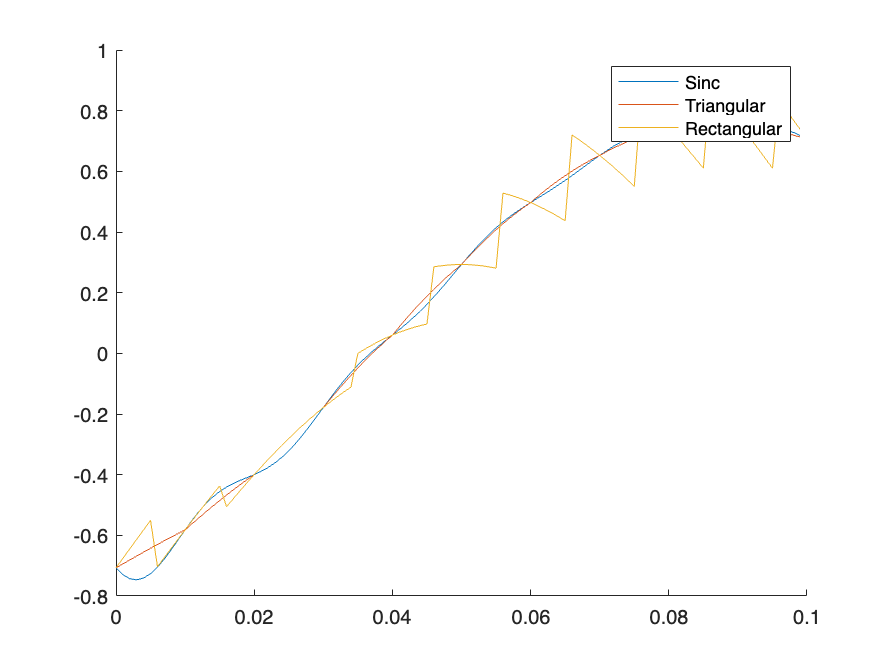



% Plot Error of Reconstruction
figure
hold on
plot(t(1:100),sin(10*pi*t(1:100)')-x_analog1(1:100)) % Plot sinc Error
plot(t(1:100),sin(10*pi*t(1:100)')-x_analog2(1:100)) % Plot triangular Error
plot(t(1:100),sin(10*pi*t(1:100)')-x_analog3(1:100)) % Plot rectangular Error
hold off
legend('Sinc','Triangular','Rectangular')

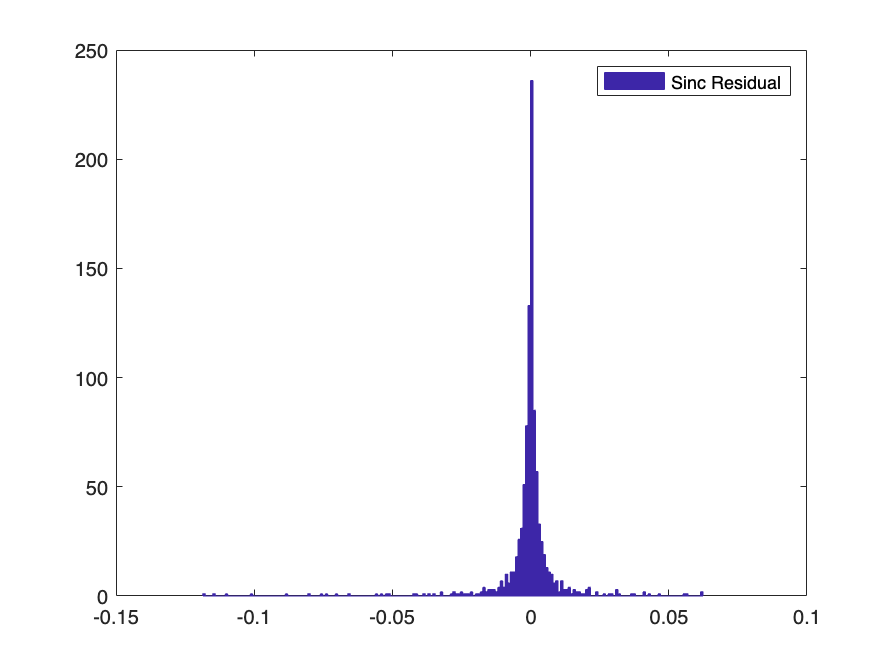


% Plot of Distributions of residuals

figure
hist(r1,200) % Histogram of r1
legend('Sinc Residual')

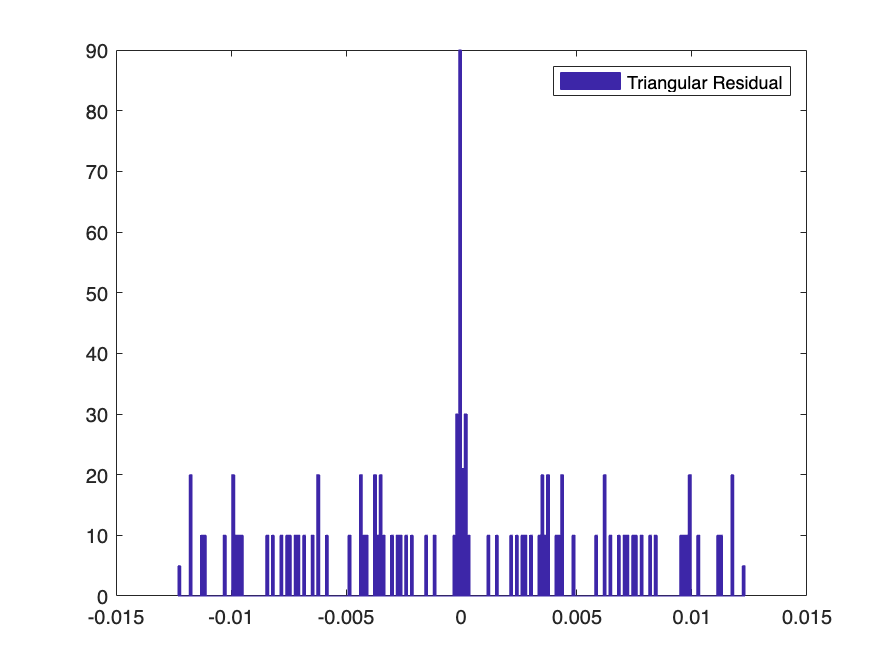

figure
hist(r2,200) % Histogram of r2
legend('Triangular Residual')

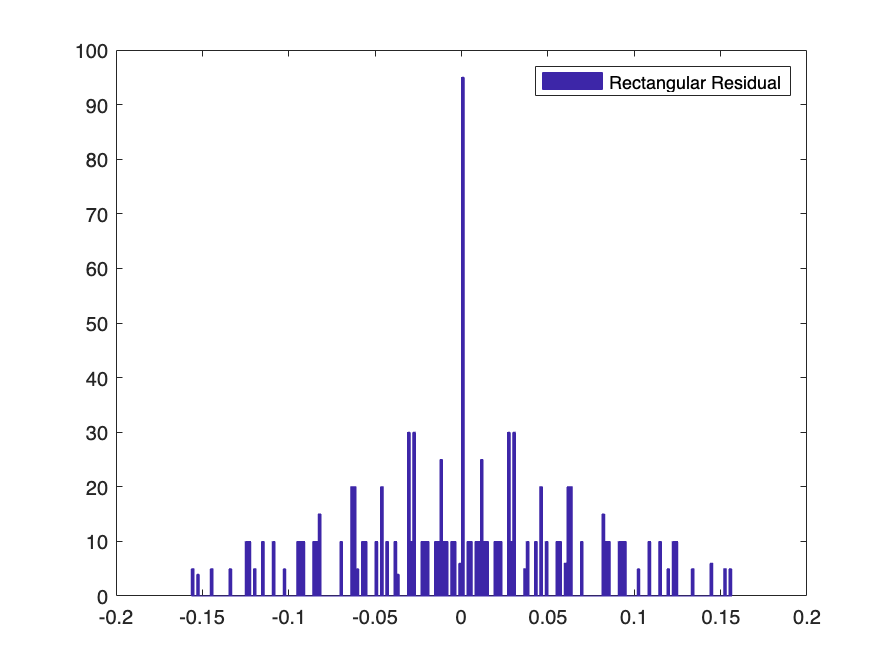

figure
hist(r3,200) % Histogram of r3
legend('Rectangular Residual')



MSE = [mean(r1.^2) mean(r2.^2) mean(r3.^2) ]

MSE =     0.0002    0.0000    0.0042


STD = [std(r1) std(r2) std(r3)]

STD =     0.0129    0.0064    0.0647


## Άσκηση 2

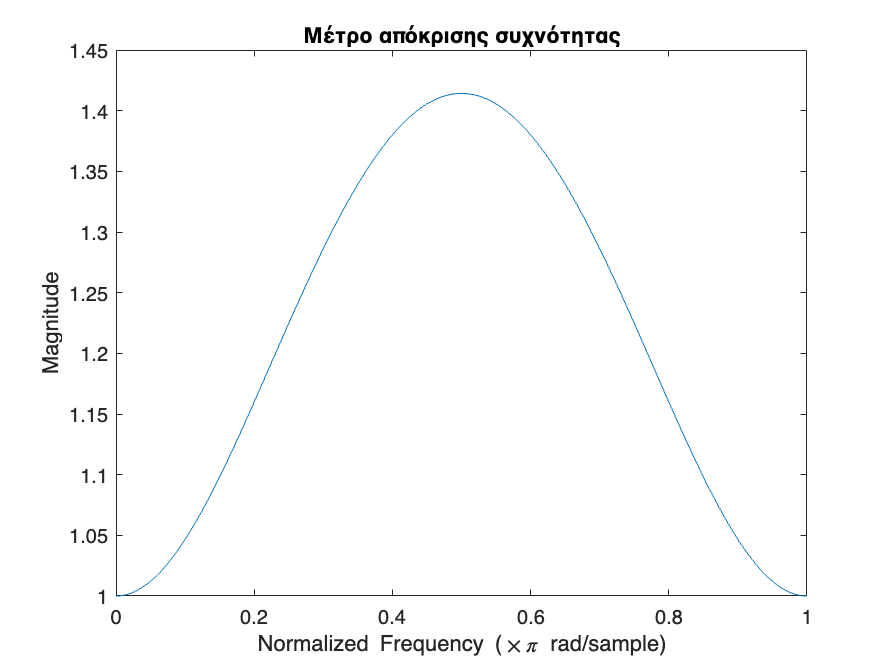

% Η κρουστική απόκρουση του συστήματος
h = [1/2, 1, -1/2];

% Ορισμός χίλιων δειγμάτων για τη συνάρτηση
[H, w] = freqz(h, 1,1000);

% Κανονικοποιημένο γράφημα μέτρου απόκρισης συχνότητας
figure
plot(w/pi, abs(H))
title('Μέτρο απόκρισης συχνότητας')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude')

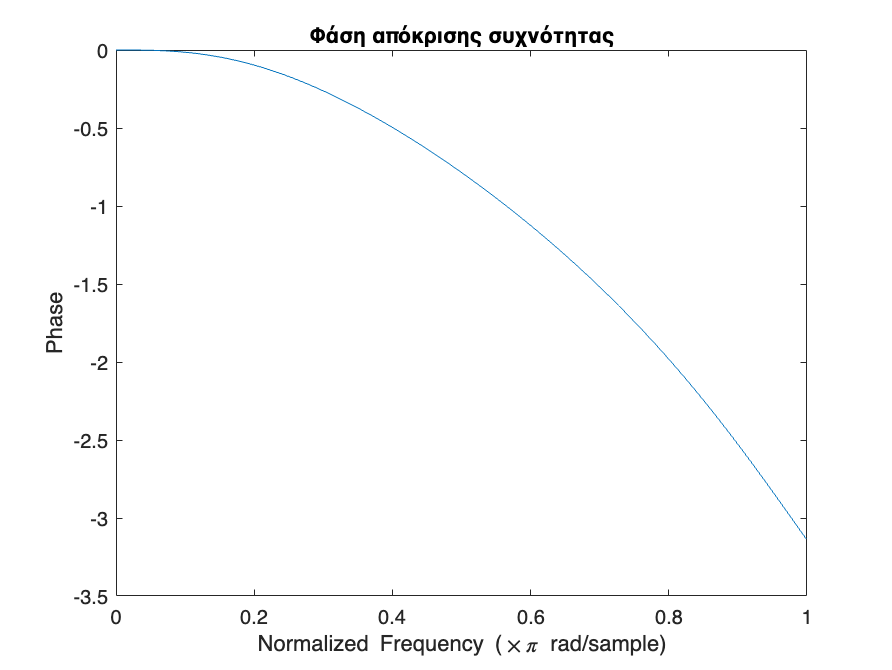


% Κανονικοποιημένο γράφημα φάσης απόκρισης συχνότητας
figure
plot(w/pi, angle(H))
title('Φάση απόκρισης συχνότητας')
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Phase')

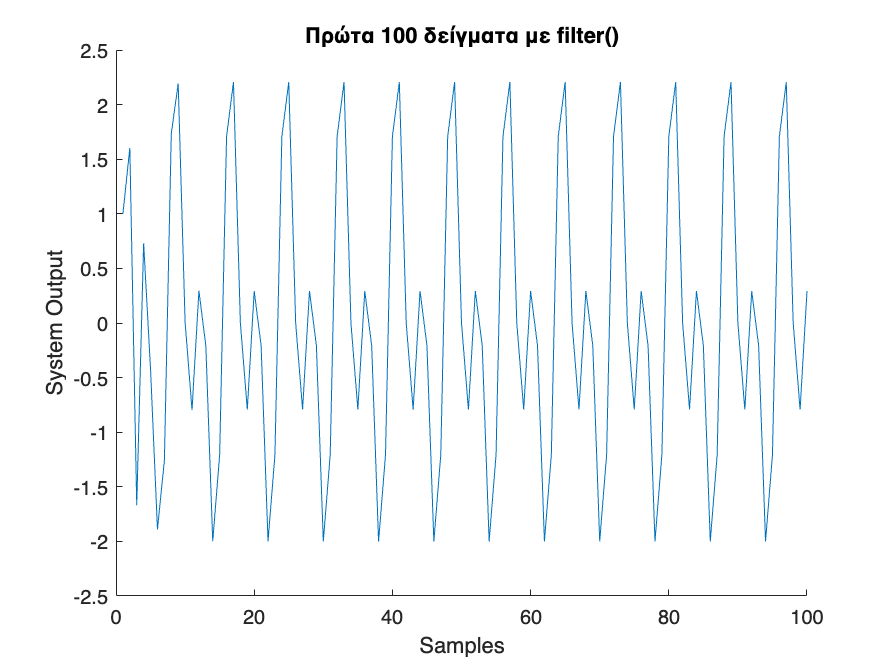



% Ορισμός του σήματος x[n]
n = 0:16000;
x = cos(pi.*n/4) - sin(pi.*n/2) + (-1/2).^n;


% Υπολογισμός εξόδου

% Με filter
y = filter(h, 1, x);
figure
%plot(x(1:100))
hold on
plot(y(1:100))
title('Πρώτα 100 δείγματα με filter()')
xlabel('Samples')
ylabel('System Output')
%legend ('Input x','filter()')
hold off

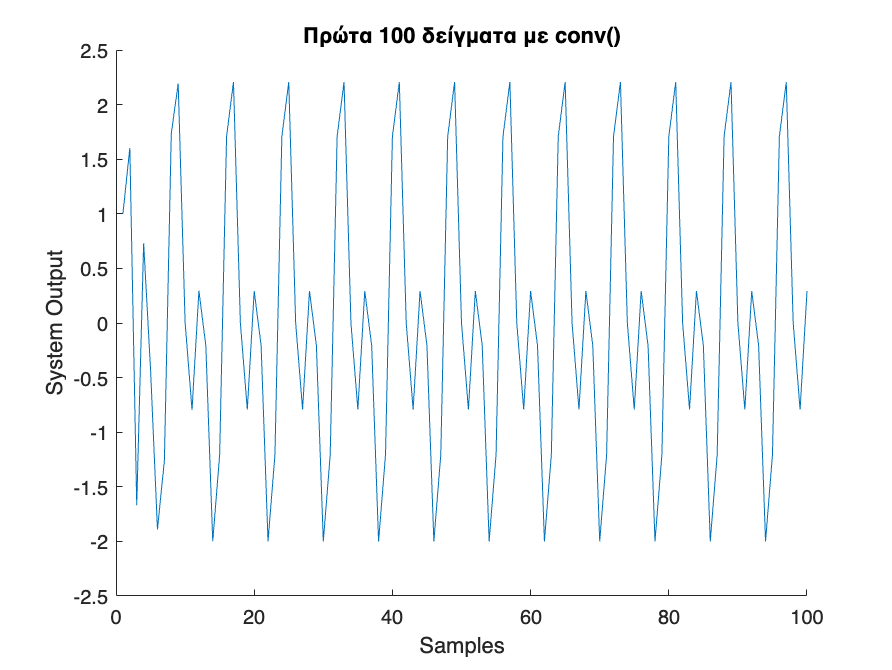



% Με conv
y = conv(h, x);
figure
%plot(x(1:100));
hold on
plot(y(1:100))
title('Πρώτα 100 δείγματα με conv()')
xlabel('Samples')
ylabel('System Output')
hold off

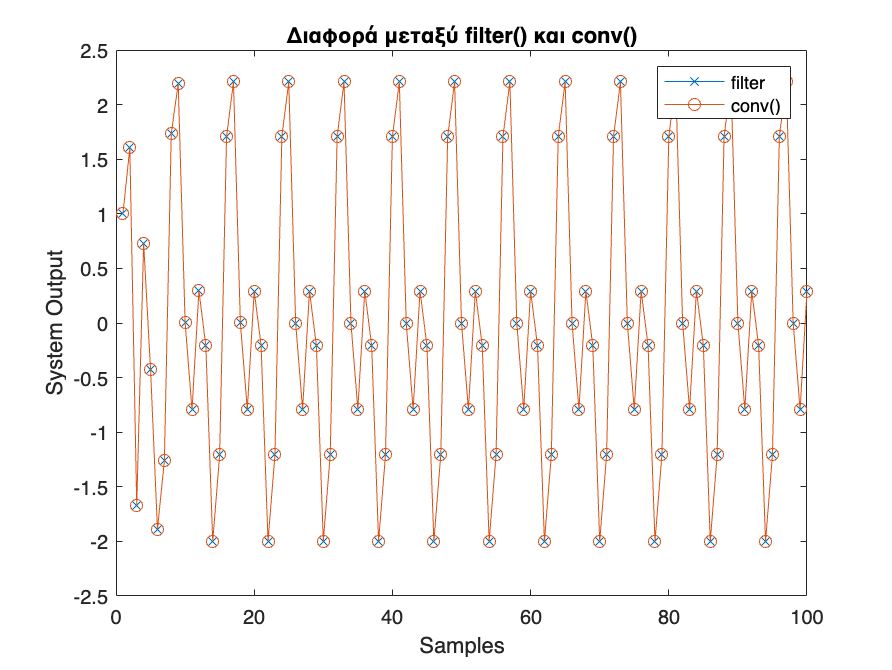

%legend ('Input x','conv()')

% Σύγκριση
figure
y = filter(h, 1, x);
plot(y(1:100),'x-')
hold on
y = conv(h, x);
plot(y(1:100),'o-')
title('Διαφορά μεταξύ filter() και conv()')
xlabel('Samples')
ylabel('System Output')
legend ('filter','conv()')
hold off

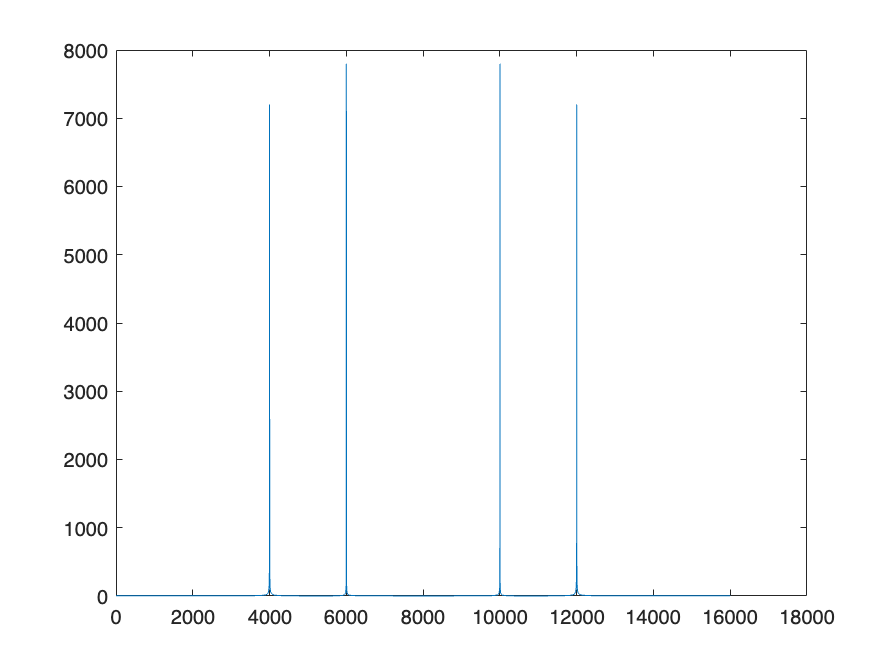


plot(abs(fftshift(fft(x))))

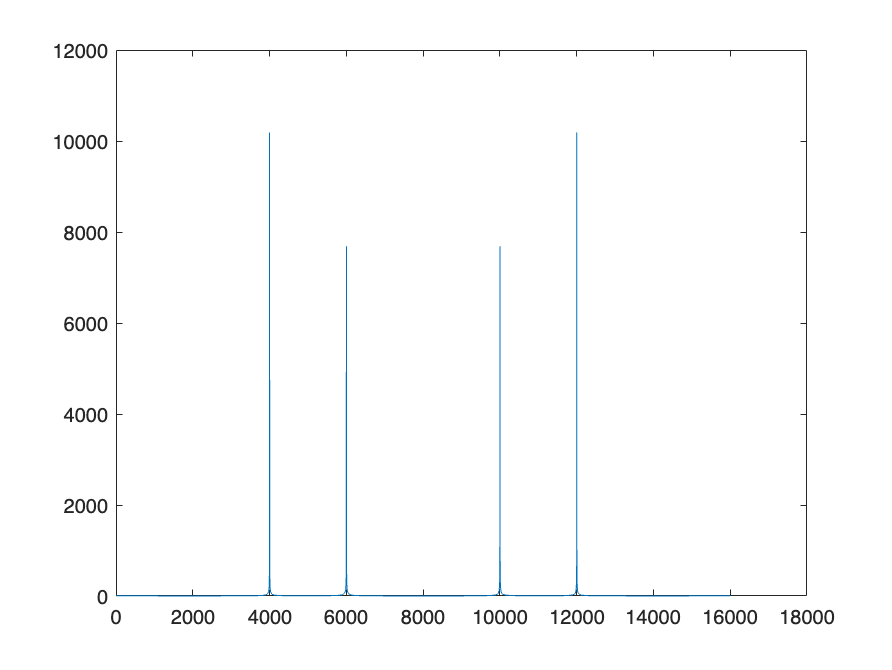


plot(abs(fftshift(fft(y))))

TimeofLine = zeros(1,2);
Time = zeros(10,2);

for n = 6:15
    for j = [0,1]
        x = rand((2^n)-j,1);
        tic;
        for i = 1:10000
            fft(x);
        end
        TimeofLine(j+1) = toc;
    end
    Time(n-5,:) = TimeofLine';
end
Time

Time =     0.0100    0.0119
    0.0086    0.0304
    0.0108    0.0208
    0.0151    0.0594
    0.0225    0.0791
    0.0446    0.3296
    0.0872    0.1894
    0.2048    1.8574
    0.4884    3.8031
    1.3568    9.4471
